# Newton’s Divided-Difference Formula

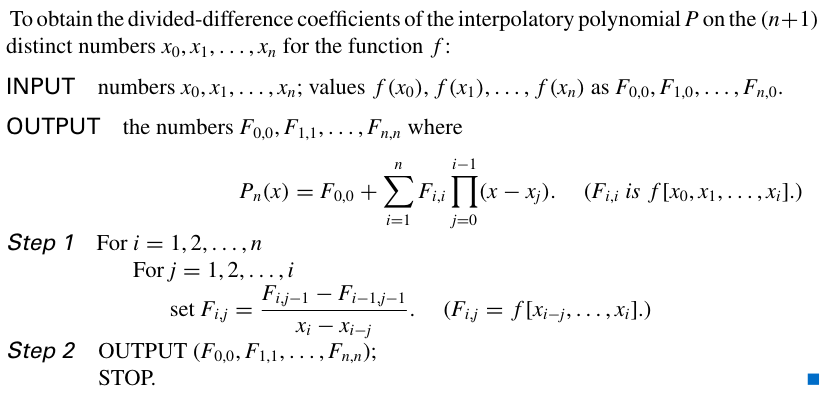

Clear Previous Data

clc;
clear;

Input the initial point:

X = [1.0 1.3 1.6 1.9]; % Initial Value
xvalue=1.5;            % Approximation Value
n = size(X);
n = n(2);
F=[];
for i = 1:n
    Y(i)=func(X(i));   %Exact value for Y
end

## Iteration Rule

Start build the interated Interpolation:


$$F_{i, j}=\frac{F_{i, j-1}-F_{i-1, j-1}}{x_{i}-x_{i-j}}$$


for i = 1:n
    F(i,1)=Y(i); %Input the value in Q(i+1,0+1)
end

for i=2:n
    for j=2:i
        F(i,j)=(F(i,j-1)-F(i-1,j-1))/(X(i)-X(i-j+1));
    end
end

## Appendix Function

function y = func(x)
    y=x^2;
end